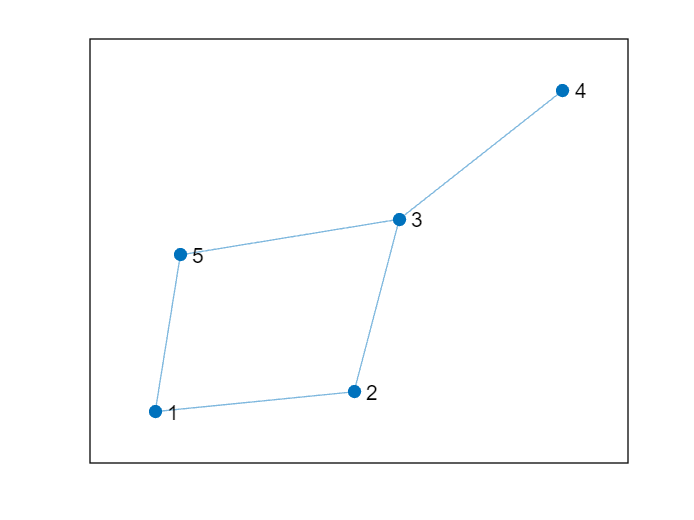

clear, clc, clf

A = [
    0, 1, 0, 0, 1;
    1, 0, 1, 0, 0;
    0, 1, 0, 1, 1;
    0, 0, 1, 0, 0;
    1, 0, 1, 0, 0;
];

G = graph(A);
figure
plot(G)

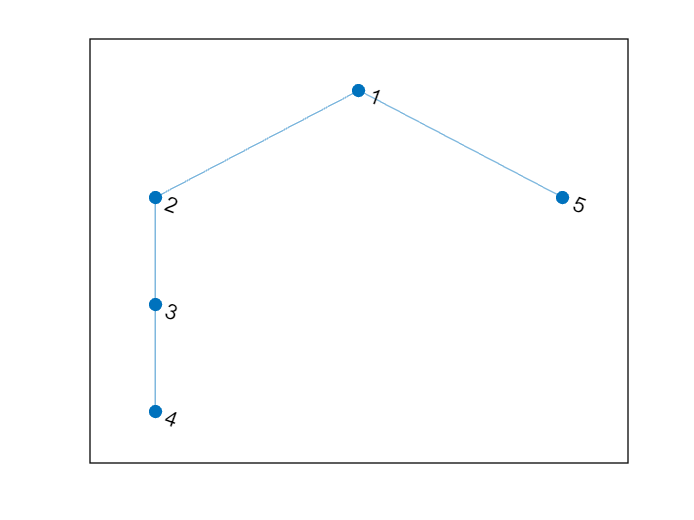

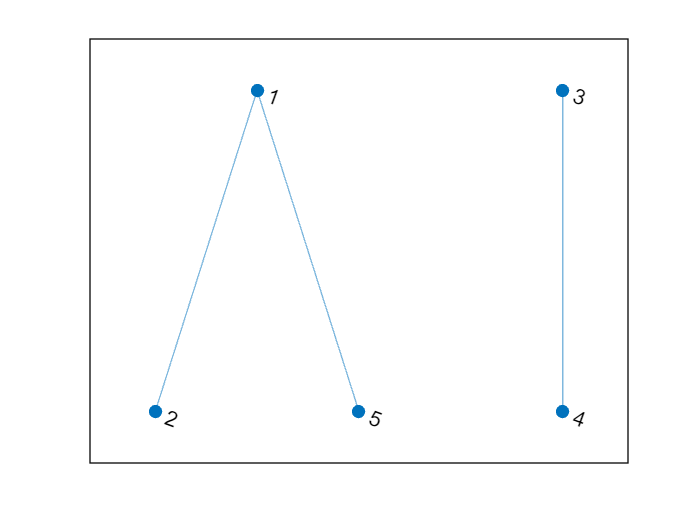

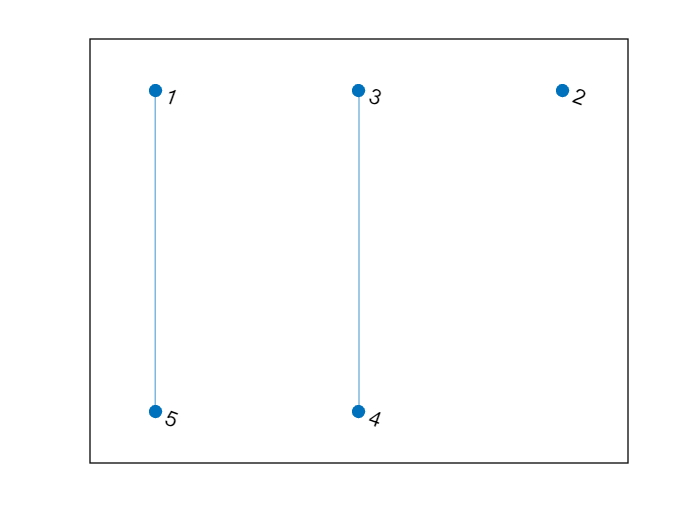


arista = [3, 5];

res = perteneceCiclo(A, arista);


disp(res);

   1



function res = perteneceCiclo(A, arista)
    % Dimensiones matriz de adyacencia
    [fil, col] = size(A);

    % Matriz de adyacencia debe ser:
    if ~(fil == col ... % Cuadrada
        && isequal(A, A')) % Simétrica

        disp('Error: Matriz de adyacencia no válida');
        res = false;
        return
    end

    % La arista debe tener:
    if ~(length(arista) == 2 ... % Dos componentes
        && all(arista == round(arista)) ... % Valores enteros
        && arista(1) ~= arista(2) ... % No ciclos propios
        && all(arista >= 1 & arista <= fil)) % Valores entre 1 y nº de aristas

        disp('Error: Arista no válida');
        res = false;
        return
    end
    
    % Se elimina la arista que queremos comprobar
    A(arista, flip(arista)) = 0;
    
    % Se recorrerá el grafo empezando por el nodo determinado por la primera componente de la arista
    vistos = zeros(1, fil);
    vistos(arista(1)) = 1;

    % Si se puede ir de uno de sus extremos al otro tras eliminarla del grafo inicial
    % Entonces la arista pertenece a un ciclo 
    res = dfs(A, arista(1), arista(2), vistos);
end

function pertenece = dfs(grafo, actual, objetivo, vistos)
    % Vecinos al nodo actual
    vecinos = grafo(actual, :);

    % Nos interesan los nodos no visitados
    % Le restamos a los vecinos los que ya hemos visitado
    vecinos_no_visitados = find(vecinos - (vecinos & vistos));
    figure
    plot(graph(grafo))
    
    for i = 1:length(vecinos_no_visitados)
        % Se añade el visitado a los vistos
        vistos(vecinos_no_visitados(i)) = 1;

        % Si el objetivo se encuentra en los vistos terminamos
        if ismember(objetivo, find(vistos))
            pertenece = true;
            break
        end

        % Eliminamos la arista que hemos utilizado para visitar
        arista = [actual, vecinos_no_visitados(i)];
        grafo(arista, flip(arista)) = 0;

        % Por recursión se siguen visitando
        pertenece = dfs(grafo, vecinos_no_visitados(i), objetivo, vistos);
        
        % Permitimos volver hacia atrás en la recursión si pertenece
        if pertenece
            break
        end
    end
end